# optimal manipulability

num_variables = 4;
x_min = [0.5; 0.5; -pi; -pi];
x_max = [1.0; 1.0; pi; pi];
A = [1 1 0 0;-1 1 0 0];
b = [1.2; 0.0];

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


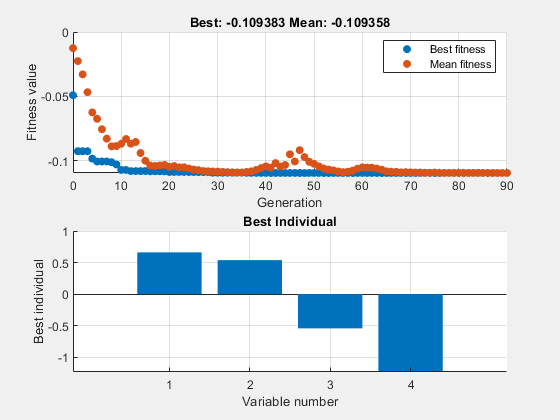

% Set nondefault solver options
options = optimoptions('ga','PlotFcn',{'gaplotbestf','gaplotbestindiv'});

% Solve
[solution,objectiveValue] = ga(@manipulability_measure,num_variables,A,b,[],...
    [],x_min,x_max,[],[],options);


% Clear variables
clearvars options

solution

solution =     0.6621    0.5389   -0.5430   -1.2340


objectiveValue

objectiveValue = -0.1094